eeg1_tr=trial6.eeg1;
emg1_tr=trial6.eeg7;
eeg1_tr=eeg1_tr*(3.3/4096);
emg1_tr=emg1_tr*(3.3/4096);
f_data=length(emg1_tr)/120;
t_data=1/f_data;
Time_d=[0:1:length(eeg1_tr)-1]*t_data;

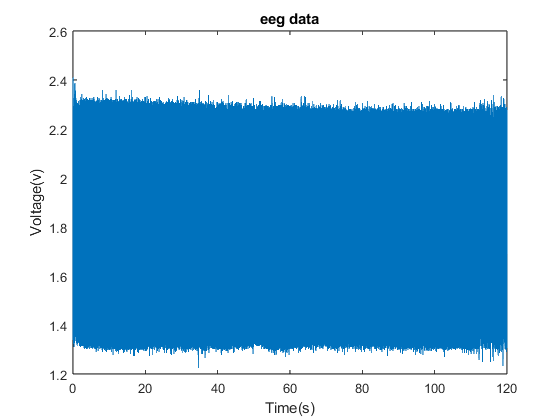

plot(Time_d,eeg1_tr)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

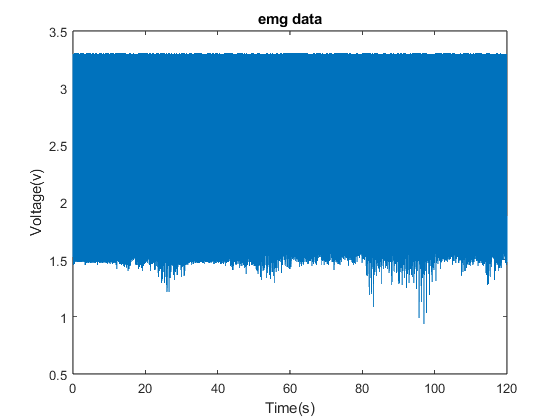

plot(Time_d,emg1_tr)
title('emg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

eeg1_tr_fft=fft(eeg1_tr);
eeg1_tr_fft(1)=0;
eeg1_tr=ifft(eeg1_tr_fft);

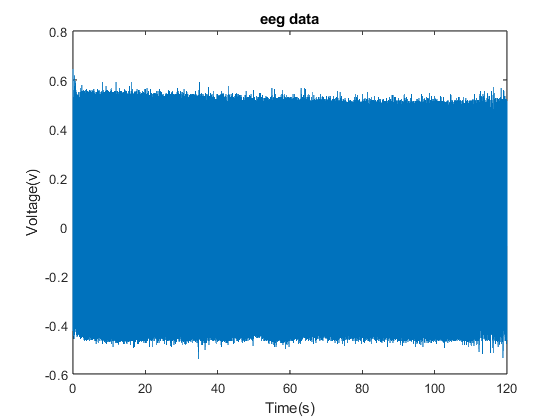

plot(Time_d,eeg1_tr)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

eeg1_tr_fft=fft(emg1_tr);
eeg1_tr_fft(1)=0;
emg1_tr=ifft(eeg1_tr_fft);

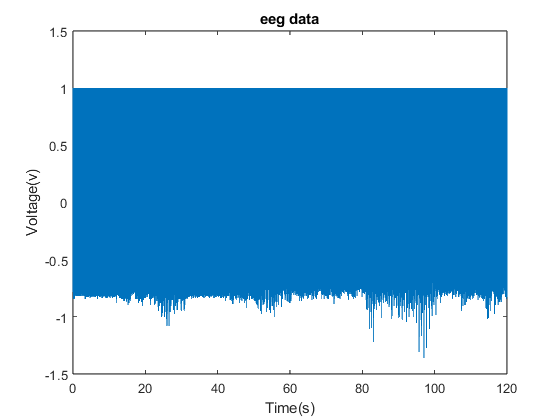

plot(Time_d,emg1_tr)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

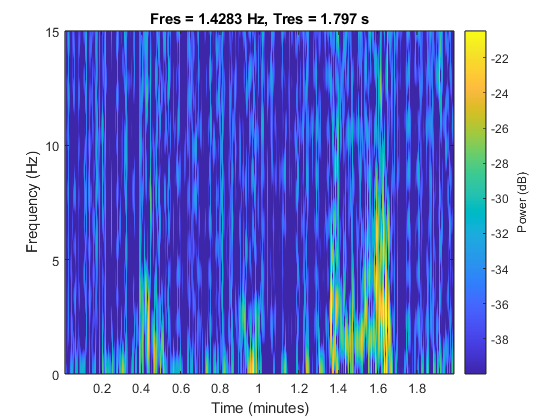

pspectrum(emg1_tr,f_data,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-40,"OverlapPercent",90,"TimeResolution",1.8);

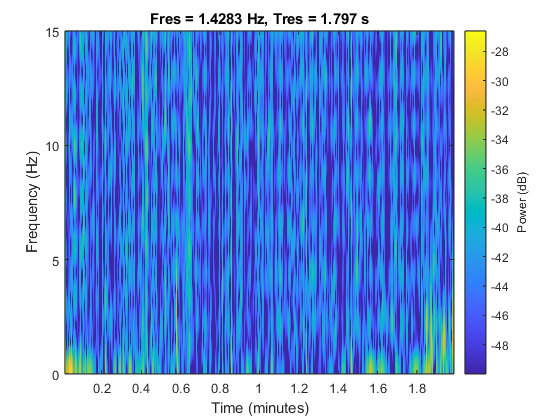

pspectrum(eeg1_tr,f_data,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-50,"OverlapPercent",90,"TimeResolution",1.8);

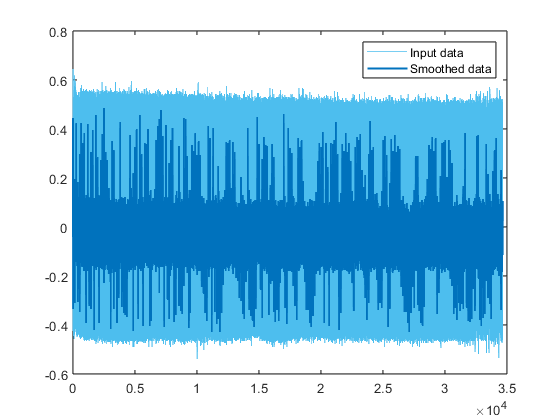

% Smooth input data
eeg_smooth = smoothdata(eeg1_tr,"movmedian",[5 0]);

% Display results
clf
plot(eeg1_tr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eeg_smooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

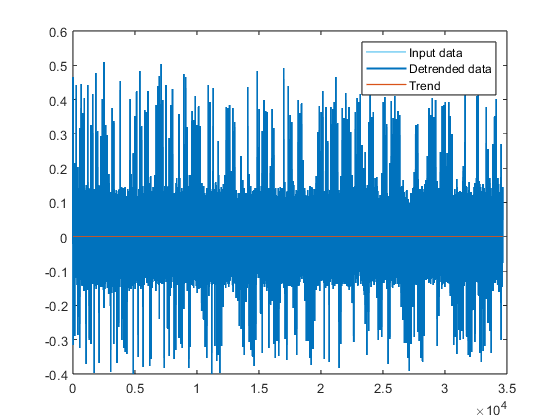

% Remove trend from data
eeg_smooth = detrend(eeg_smooth,2);

% Display results
clf
plot(eeg_smooth,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eeg_smooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(eeg_smooth-eeg_smooth,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

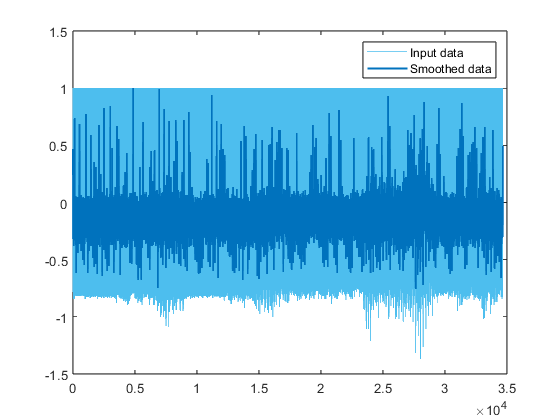

% Smooth input data
emg_smooth = smoothdata(emg1_tr,"movmedian",[1 4]);

% Display results
clf
plot(emg1_tr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(emg_smooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

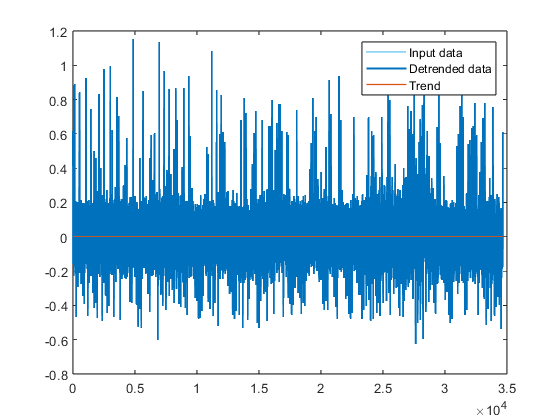

% Remove trend from data
emg_smooth = detrend(emg_smooth);

% Display results
clf
plot(emg_smooth,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(emg_smooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(emg_smooth-emg_smooth,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

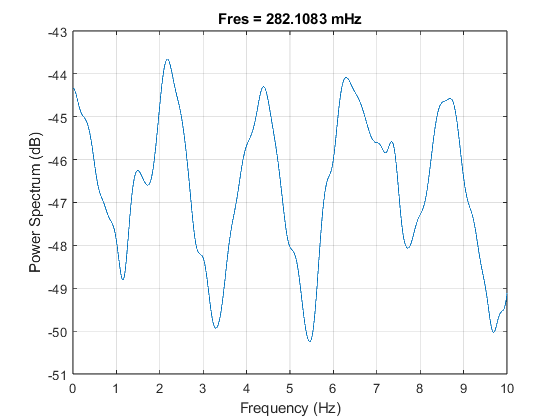

pspectrum(eeg_smooth,f_data,"power","FrequencyLimits",[0,10])%"FrequencyLimits",[0,15],"MinThreshold",-40,"OverlapPercent",90,"TimeResolution",1);

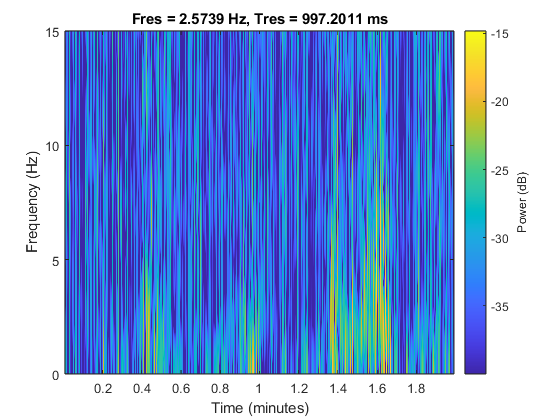

pspectrum(emg_smooth,f_data,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-40,"OverlapPercent",99,"TimeResolution",1);

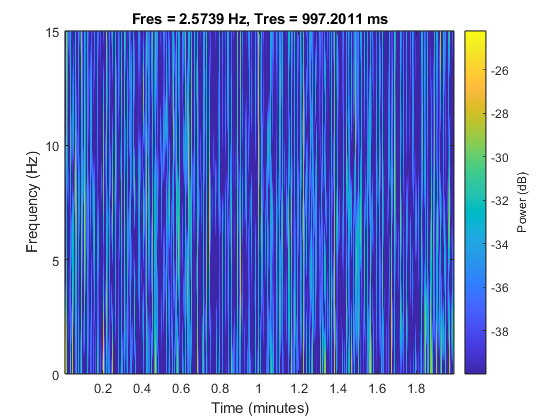

pspectrum(eeg_smooth,f_data,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-40,"OverlapPercent",99,"TimeResolution",1);

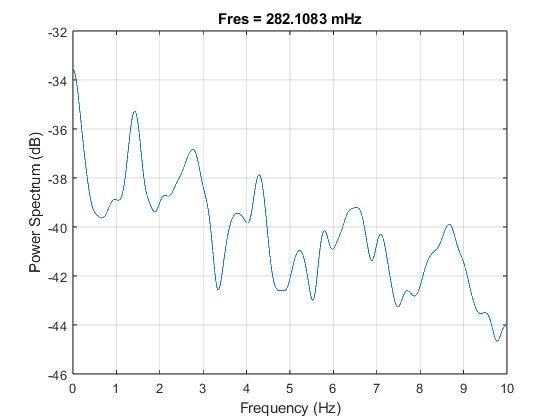

pspectrum(emg_smooth,f_data,"power","FrequencyLimits",[0,10])

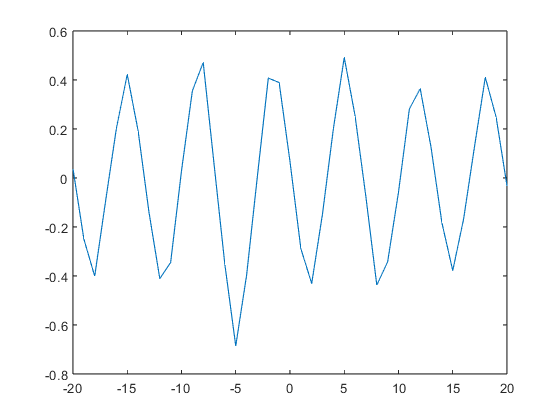

[correlated_eeg_emg,lags]=crosscorr(eeg_smooth,emg_smooth);

plot(lags,correlated_eeg_emg);

output_eeg_emg_6=[eeg1_tr,emg1_tr];
output_eeg_emg_6_smooth=[eeg_smooth,emg_smooth];


writematrix(output_eeg_emg_6_smooth,'D:\matlab\ymaps_code\data\output_eeg_emg_6_smooth.csv');
writematrix(output_eeg_emg_6,'D:\matlab\ymaps_code\data\output_eeg_emg_6.csv');